# 1

a)

probs = [0.3, 0.2, 0;
        0.1, 0.15, 0.05;
        0, 0.1, 0.1]

probs =     0.3000    0.2000         0
    0.1000    0.1500    0.0500
         0    0.1000    0.1000


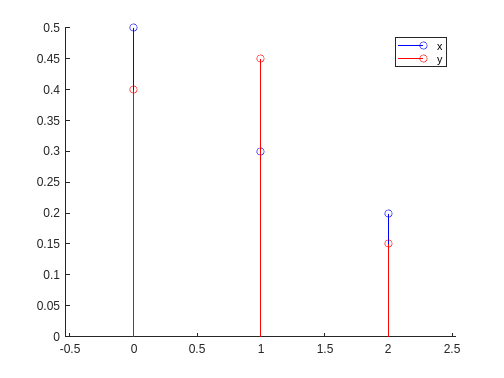

funcao_massa_probabilidade_x = [0.5 , 0.3, 0.2];
funcao_massa_probabilidade_y = [0.4, 0.45, 0.15];
hold on
stem(0:2,funcao_massa_probabilidade_x,'b')
stem(0:2, funcao_massa_probabilidade_y,'r')
legend("x","y")
hold off

b)

media_de_x = sum(funcao_massa_probabilidade_x .* [0 1 2]);
variancia_x = sum(funcao_massa_probabilidade_x .* ([0 1 2].^2)) - (media_de_x.^2);
media_de_y = sum(funcao_massa_probabilidade_y .* [0 1 2]);
variancia_y = sum(funcao_massa_probabilidade_y .* ([0 1 2].^2)) - (media_de_y.^2);

c)

correlacao = 0;
for i = 0:2
    for j = 0:2
        correlacao = correlacao + i.*j.*probs(i+1,j+1);
    end
end
covariancia = correlacao - (media_de_y*media_de_x);
coeficiente_correlacao = covariancia/((sqrt(variancia_y)).*(sqrt(variancia_x)));

# 2

a)

probs_2a = [1/8,1/8,1/24;
            1/8,1/4,1/8;
            1/24,1/8,1/24];
funcao_massa_probabilidade_x_2a = sum(probs_2a,2)';
funcao_massa_probabilidade_y_2a = sum(probs_2a,1);
false = 0;
for i = 1:3
    if probs_2a(i,i) ~= (funcao_massa_probabilidade_x_2a(i).*funcao_massa_probabilidade_y_2a(i))
        false = 1;
    end
end
false;

# 3

a)

N1 = (randn(120,1)'.*sqrt(14/4)) + 14;
N2 = (randn(120,1)'.*sqrt((14*1.20)/4)) + 14*1.20;
N1 = floor(N1);
N2 = floor(N2);

b)

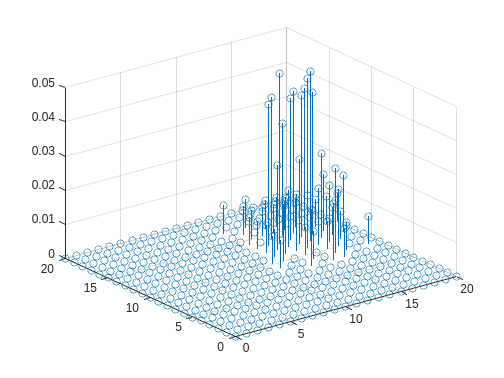

valores = configureDictionary("string","double");
for i = 1:120
    if ismember(strcat(int2str(N1(i)),"_",int2str(N2(i))),keys(valores))
        valores(strcat(int2str(N1(i)),"_",int2str(N2(i)))) = valores(strcat(int2str(N1(i)),"_",int2str(N2(i)))) + 1;
    else
        valores = insert(valores,strcat(int2str(N1(i)),"_",int2str(N2(i))),1);
    end
end
funcao_massa_probabilidade_3b = values(valores) ./ 120;
k = keys(valores);
for i = 1:size(k,1)
    valores(k(i)) = funcao_massa_probabilidade_3b(i);
end
z_3b = zeros(21,21);
for i = 1:size(k,1)
    value = split(k(i),'_');
    z_3b(str2num(value(1)),str2num(value(2))) = valores(k(i));
end
stem3(0:20,0:20,z_3b);

c)

correlacao_2b = 0;
for i = 0:20
    for j = 0:20
        correlacao_2b = correlacao_2b + i.*j.*z_3b(i+1,j+1);
    end
end
covariancia_2b = correlacao_2b - (14*(14*1.20));
coeficiente_correlacao_2b = covariancia_2b/((14/4).*((14*1.20)/4));

d)

false_3b = 0;
massa_probabilidade_x_3d = sum(z_3b,2)';
massa_probabilidade_y_3d = sum(z_3b,1);
for i = 1:21
    if z_3b(i,i) ~= (massa_probabilidade_x_3d(i).*massa_probabilidade_y_3d(i))
        false_3b = 1;
    end
end
false_3b;

# 4

P_sol = 0.75;
P_chuva = 0.25;
P_prev_sol_dado_sol = 1/3;
P_prev_chuva_dado_chuva = 1;

P_prev_sol_e_sol = P_prev_sol_dado_sol * P_sol;
P_prev_chuva_e_sol = (1 - P_prev_sol_dado_sol) * P_sol;
P_prev_sol_e_chuva = 0;
P_prev_chuva_e_chuva = P_prev_chuva_dado_chuva * P_chuva;


P_conjunta = [P_prev_sol_e_sol, P_prev_chuva_e_sol;
              P_prev_sol_e_chuva, P_prev_chuva_e_chuva];

exatidao = P_prev_sol_e_sol + P_prev_chuva_e_chuva

exatidao = 0.5000

exatidao_sempre_sol = P_sol

exatidao_sempre_sol = 0.7500